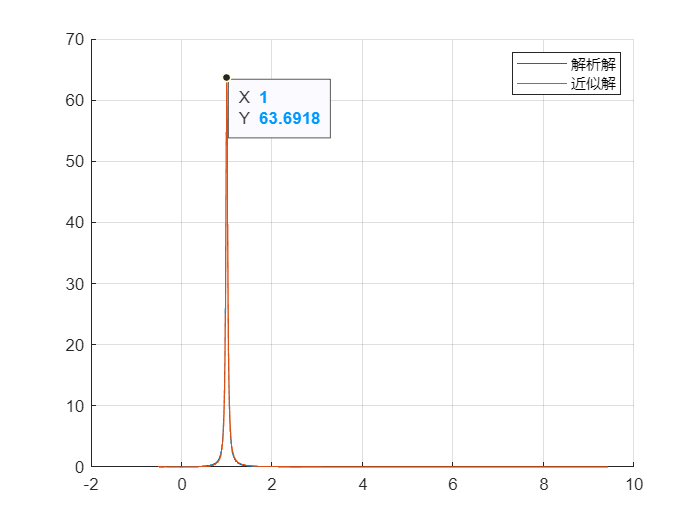

q = 1;
C = 1;
omega0 = 1;
gamma = 0.05;

omega = -0.5:0.01:3*pi;
V1 = (1/8/pi)*(q/C)^2*(1./((omega-omega0).^2+(gamma/2)^2));
V2 = (1/sqrt(2*pi))*(0.025+1j.*omega)./((0.025+1j.*omega).^2+1);
V3 = (1/sqrt(2*pi))*(0.025-1j.*omega)./((0.025-1j.*omega).^2+1);
V2=V2.*V3;
hold on
plot(omega, V1)
plot(omega,V2)
grid on
legend('解析解', '近似解')

ax = gca;
chart = ax.Children(1);
datatip(chart,1,63.69);